# **Session 1: Working with an existing data pipeline with DataJoint**

This live scripts introduce how to work with an existing data pipeline, we will cover the following topics:

- Check schema structure and table definitions

- Flexible queries

- Fetching from query results

## Schema structure and table definitions

Schemas are groups of tables that are intuitively related. In the U19 pipeline, we have the following schemas:

- lab: the lab schema contains general information of the lab

- subject: the subject schema contains information about the animals

- action: the action schema contains water, weighing, and action item information

- acquisition: the acquisition schema contains behavioral information, and also the scanning information of the two-photon recording

- imaging: the imaging schema contains the processing steps of the two-photon imaging experiments.

To check the schema structure, we could use `erd` to draw a diagram

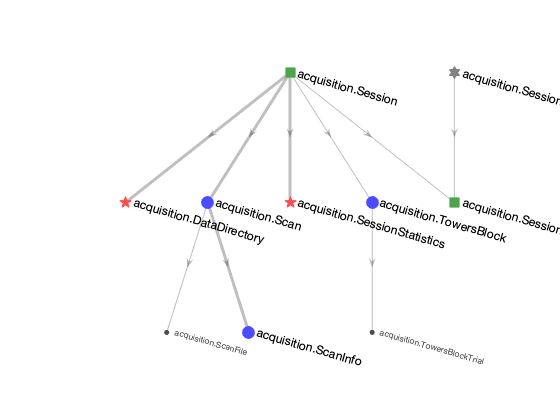

erd acquisition

There are five types of tables:

- Manual tables (green squares): tables for manual information, such as Subject, lost if deleted

- Lookup tables (gray stars): tables for general information, such as some parameter settings

- Imported tables (blue dots): tables that are ingested from external files, such as recording tiff files from two-photon imaging, allowing auto-populate. When deleted, the entries were recoverable if the external files still exist.

- Computed tables (red stars): tables that are computed from tables within the database, allow auto-populate. Easily recoverable when the entries are deleted.

- Part tables (gray little dots): allow insertion by their master tables.

There are three types of table dependencies:

- One to one: child table and its parent table has the exact same primary key.

- One to many: other than the primary key of the parent table, the child table has some other fields as part of primary key

- Secondary attribute dependency: a secondary attribute is a field of the primary key of another table

- Many to many: implemented with two one-to-many dependencies

We could use `describe` to check a table definition. The --- separates the primary key and secondary attributes, -> indicates a dependency to its parent table. For example, the table subject.Subject has a one-to-many dependency with its parent table lab.User

describe(subject.Subject)

ans =     '%{
     # 
     -> lab.User
     subject_id                  : char(8)                       # nickname
     ---
     genomics_id=null            : int                           # number from the facility
     sex="Unknown"               : enum('Male','Female','Unknown') # sex
     dob=null                    : date                          # birth date
     head_plate_mark=null        : blob                          # little drawing on the head plate for mouse identification
     -> lab.Location
     -> lab.Protocol
     -> subject.Line
     subject_description         : varchar(255)                  # description
     initial_weight=null         : float                         # 
     %}
     '


We could also directly print out a table to get an overview of the table contents, the primary key columns are CAPITALIZED

subject.Subject

ans = Object subject.Subject

 ::  ::

    USER_ID     SUBJECT_ID    genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    head_plate_mark
    ________    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    _______________

    'ben'        'B205'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES-CRE'            ''                   27             '=BLOB='    
    'ben'        'B208'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES

Another example, 

action.Weighing

ans = Object action.Weighing

 ::  ::

    USER_ID    SUBJECT_ID        WEIGHING_TIME        weigh_person       location        weight    weight_notice
    _______    __________    _____________________    ____________    _______________    ______    _____________

     'ben'       'B205'      '2018-06-20 12:52:00'      'ben'         'pni-174cr4jk2'       26          ''      
     'ben'       'B205'      '2018-06-21 16:53:00'      'ben'         'pni-174cr4jk2'     25.5          ''      
     'ben'       'B205'      '2018-06-23 04:39:00'      'ben'         'pni-174cr4jk2'       25          ''      
     'ben'       'B205'      '2018-06-24 21:22:00'      'ben'         'pni-174cr4jk2'       26          ''      
     'ben'       'B205'      '2018-06-25 15:

## Flexible Queries

DataJoint supports powerful but intuitive queries. We will list a few important ones:

- Restriction (filter): & or -, filter the entries with some criteria.

- Join: *, gather fields together from different tables.

- proj(): only focus on a subset of secondary attribute, rename field and simple computation

- aggr(): simple computations on one against some other tables

### Restrictions (Filters)  & takes multiple forms

% restrictor as a string
subject.Subject & 'user_id = "edward"' & 'or initial_weight != 30'

ans = Object subject.Subject

 ::  ::

    USER_ID     SUBJECT_ID    genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    head_plate_mark
    ________    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    _______________

    'ben'        'B205'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES-CRE'            ''                   27             '=BLOB='    
    'ben'        'B208'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES

% restrictor as a string, unequal
subject.Subject & 'dob > "2019-01-01"'

ans = Object subject.Subject

 ::  ::

     USER_ID      SUBJECT_ID    genomics_id      sex           dob          location     protocol        line        subject_description    initial_weight    head_plate_mark
    __________    __________    ___________    ________    ____________    __________    ________    ____________    ___________________    ______________    _______________

    'lucas'       'SP2'             NaN        'Female'    '2019-03-27'    'vivarium'     '1910'     'Unknown'               ''                  22.4            '=BLOB='    
    'lucas'       'SP3'             NaN        'Female'    '2019

% restrictor as a string, within a range
subject.Subject & 'dob between "2019-01-01" and "2019-02-01"'

ans = Object subject.Subject

 ::  ::

     USER_ID      SUBJECT_ID    genomics_id      sex           dob          location     protocol          line          subject_description    initial_weight    head_plate_mark
    __________    __________    ___________    ________    ____________    __________    ________    ________________    ___________________    ______________    _______________

    'mioffe'       'M5_696'         NaN        'Female'    '2019-01-21'    'vivarium'     '1910'     'Unknown'                   ''                   15             '=BLOB='    
    'testuser'     'T01'            NaN        'Fema

% restrictor as a string, "or" 
subject.Subject & 'sex in ("Male", "Female")'

ans = Object subject.Subject

 ::  ::

    USER_ID     SUBJECT_ID    genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    head_plate_mark
    ________    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    _______________

    'ben'        'B205'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES-CRE'            ''                   27             '=BLOB='    
    'ben'        'B208'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES

% restrictor as a string, "or" 
subject.Subject & 'sex = "Male" or sex = "Female"'

ans = Object subject.Subject

 ::  ::

    USER_ID     SUBJECT_ID    genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    head_plate_mark
    ________    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    _______________

    'ben'        'B205'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES-CRE'            ''                   27             '=BLOB='    
    'ben'        'B208'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES

For more syntax of restrictors as a string, check on MYSQL syntax. DataJoint supports most of the MYSQL syntax.

DataJoint also takes a struct as a restrictor:

subject.Subject & struct('user_id', 'ben', 'sex', 'Male')

ans = Object subject.Subject

 ::  ::

    USER_ID    SUBJECT_ID    genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    head_plate_mark
    _______    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    _______________

     'ben'      'B205'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES-CRE'            ''                   27             '=BLOB='    
     'ben'      'B208'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES-CRE

Retrictor as a array of struct perform the 'or' logic.

subject.Subject & [struct('user_id', 'ben', 'sex', 'Male'), struct('user_id', 'edward', 'sex', 'Male')]

ans = Object subject.Subject

 ::  ::

    USER_ID     SUBJECT_ID    genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    head_plate_mark
    ________    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    _______________

    'ben'        'B205'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES-CRE'            ''                   27             '=BLOB='    
    'ben'        'B208'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES

acquisition.Session

ans = Object acquisition.Session

 ::  ::

    USER_ID    SUBJECT_ID    SESSION_DATE    SESSION_NUMBER     session_start_time        session_end_time        location       task      level    set_id    stimulus_bank    stimulus_commit    stimulus_set    ball_squal    session_performance    session_narrative    protocol    version_info
    _______    __________    ____________    ______________    _____________________    _____________________    __________    ________    _____    ______    _____________

Restrict with other tables.

All mice that have a session

subject.Subject - acquisition.Session().proj()

ans = Object subject.Subject

 ::  ::

    USER_ID     SUBJECT_ID    genomics_id      sex           dob          location     protocol        line        subject_description    initial_weight    head_plate_mark
    ________    __________    ___________    ________    ____________    __________    ________    ____________    ___________________    ______________    _______________

    'edward'    'E42'             NaN        'Male'      ''              'vivarium'     '1910'     'Unknown'               ''                    27            '=BLOB='    
    'edward'    'E71'             NaN        'Female'    '2017-11-20' 

All forms of restrictors could be combined:

subject.Subject & [struct('user_id', 'ben', 'sex', 'Male'), struct('user_id', 'edward', 'sex', 'Male')] & 'subject_id="B205"'

ans = Object subject.Subject

 ::  ::

    USER_ID    SUBJECT_ID    genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    head_plate_mark
    _______    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    _______________

     'ben'       'B205'          NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES-CRE'            ''                   27             '=BLOB='    

1 tuples (0.187 s)


### Join `*` gathers fields from different tables together

subject.Subject * action.WaterAdministration

ans = Object dj.internal.GeneralRelvar

    USER_ID    SUBJECT_ID       TASK       genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    task_description    head_plate_mark
    _______    __________    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    ________________    _______________

     'ben'      'B205'       'AirPuffs'        NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES-CRE'          

### Projection `proj(`) only keeps a subset of the secondary attributes

No arguments:

% with no arguments it only keeps the primary key
subject.Subject().proj()

ans = Object dj.internal.GeneralRelvar

    USER_ID     SUBJECT_ID
    ________    __________

    'ben'        'B205'   
    'ben'        'B208'   
    'ben'        'B3151'  
    'ben'        'B4486'  
    'ben'        'B4487'  
    'ben'        'B4488'  
    'ben'        'B4489'  
    'edward'     'E18'    
    'edward'     'E26'    
    'edward'     'E36'    
    'edward'     'E38'    
    'edward'     'E39'    

          ...

175 tuples (0.122 s)


It also works like this.

proj(subject.Subject)

ans = Object dj.internal.GeneralRelvar

    USER_ID     SUBJECT_ID
    ________    __________

    'ben'        'B205'   
    'ben'        'B208'   
    'ben'        'B3151'  
    'ben'        'B4486'  
    'ben'        'B4487'  
    'ben'        'B4488'  
    'ben'        'B4489'  
    'edward'     'E18'    
    'edward'     'E26'    
    'edward'     'E36'    
    'edward'     'E38'    
    'edward'     'E39'    

          ...

175 tuples (0.0455 s)


Actually this is more commonly used because adding filters to this is easy.

proj(subject.Subject & 'user_id="ben"')

ans = Object dj.internal.GeneralRelvar

    USER_ID    SUBJECT_ID
    _______    __________

     'ben'      'B205'   
     'ben'      'B208'   
     'ben'      'B3151'  
     'ben'      'B4486'  
     'ben'      'B4487'  
     'ben'      'B4488'  
     'ben'      'B4489'  

7 tuples (0.048 s)


Now keep some other attributes as well:

proj(subject.Subject, 'dob', 'sex')

ans = Object dj.internal.GeneralRelvar

    USER_ID     SUBJECT_ID     sex      dob
    ________    __________    ______    ___

    'ben'        'B205'       'Male'    '' 
    'ben'        'B208'       'Male'    '' 
    'ben'        'B3151'      'Male'    '' 
    'ben'        'B4486'      'Male'    '' 
    'ben'        'B4487'      'Male'    '' 
    'ben'        'B4488'      'Male'    '' 
    'ben'        'B4489'      'Male'    '' 
    'edward'     'E18'        'Male'    '' 
    'edward'     'E26'        'Male'    '' 
    'edward'     'E36'        'Male'    '' 
    'edward'     'E38'        'Male'    '' 
    'edward'     'E39'        'Male'    '' 

          ...

175 tuples (0.0648 s)


`proj()` also allows renaming the fields

proj(subject.Subject, 'dob->birth_date', 'sex')

ans = Object dj.internal.GeneralRelvar

    USER_ID     SUBJECT_ID     sex      birth_date
    ________    __________    ______    __________

    'ben'        'B205'       'Male'        ''    
    'ben'        'B208'       'Male'        ''    
    'ben'        'B3151'      'Male'        ''    
    'ben'        'B4486'      'Male'        ''    
    'ben'        'B4487'      'Male'        ''    
    'ben'        'B4488'      'Male'        ''    
    'ben'        'B4489'      'Male'        ''    
    'edward'     'E18'        'Male'        ''    
    'edward'     'E26'        'Male'        ''    
    'edward'     'E36'        'Male'        ''    
    'edward'     'E38'        'Male'        ''    
    'edward'     'E39'        'Male'        ''    

          ...

175 tuples (0.0587 s)


action.Weighing

ans = Object action.Weighing

 ::  ::

    USER_ID    SUBJECT_ID        WEIGHING_TIME        weigh_person       location        weight    weight_notice
    _______    __________    _____________________    ____________    _______________    ______    _____________

     'ben'       'B205'      '2018-06-20 12:52:00'      'ben'         'pni-174cr4jk2'       26          ''      
     'ben'       'B205'      '2018-06-21 16:53:00'      'ben'         'pni-174cr4jk2'     25.5          ''      
     'ben'       'B205'      '2018-06-23 04:39:00'      'ben'         'pni-174cr4jk2'       25          ''      
     'ben'       'B205'      '2018-06-24 21:22:00'      'ben'         'pni-174cr4jk2'       26          ''      
     'ben'       'B205'      '2018-06-25 15:

and some simple computations:

Example 1: get the date of a weighing

proj(action.Weighing & 'subject_id="B205"', 'date(weighing_time)->weighing_date')

ans = Object dj.internal.GeneralRelvar

    USER_ID    SUBJECT_ID        WEIGHING_TIME        weighing_date
    _______    __________    _____________________    _____________

     'ben'       'B205'      '2018-06-20 12:52:00'    '2018-06-20' 
     'ben'       'B205'      '2018-06-21 16:53:00'    '2018-06-21' 
     'ben'       'B205'      '2018-06-23 04:39:00'    '2018-06-23' 
     'ben'       'B205'      '2018-06-24 21:22:00'    '2018-06-24' 
     'ben'       'B205'      '2018-06-25 15:15:00'    '2018-06-25' 
     'ben'       'B205'      '2018-06-27 11:55:00'    '2018-06-27' 
     'ben'       'B205'      '2018-06-28 12:44:00'    '2018-06-28' 
     'ben'       'B205'      '2018-06-29 21:44:00'    '2018-06-29' 
     'ben'       'B205'      '2018-07-03 14:19:00'    '2018-07-03' 
     'ben'       'B205'      '2018-07-09 12:09:00'    '2018-07-09' 
     'b

Example 2: What is the age of an animal when performing each session?

% First get the date of birth and the session date into the same query
q = subject.Subject().proj('dob') * acquisition.Session().proj() & 'dob != ""'

q = Object dj.internal.GeneralRelvar

    USER_ID     SUBJECT_ID    SESSION_DATE    SESSION_NUMBER        dob     
    ________    __________    ____________    ______________    ____________

    'edward'      'E58'       '2017-10-17'          0           '2016-11-14'
    'edward'      'E58'       '2017-10-18'          0           '2016-11-14'
    'edward'      'E58'       '2017-10-19'          0           '2016-11-14'
    'edward'      'E58'       '2017-10-20'          0           '2016-11-14'
    'edward'      'E58'       '2017-10-23'          0           '2016-11-14'
    'edward'      'E58'       '2017-10-24'          0           '2016-11-14'
    'edward'      'E58'       '2017-10-25'          0           '2016-11-14'
    'edward'      'E58'       '2017-10-26'          0           '2016-11-14'
    'edward'      'E5

% Then perform the computation with proj()
q.proj('datediff(session_date, dob)->age_in_days')

ans = Object dj.internal.GeneralRelvar

    USER_ID     SUBJECT_ID    SESSION_DATE    SESSION_NUMBER    age_in_days
    ________    __________    ____________    ______________    ___________

    'edward'      'E58'       '2017-10-17'          0               337    
    'edward'      'E58'       '2017-10-18'          0               338    
    'edward'      'E58'       '2017-10-19'          0               339    
    'edward'      'E58'       '2017-10-20'          0               340    
    'edward'      'E58'       '2017-10-23'          0               343    
    'edward'      'E58'       '2017-10-24'          0               344    
    'edward'      'E58'       '2017-10-25'          0               345    
    'edward'      'E58'       '2017-10-26'          0               346    
    'edward'      'E58'      

 Aggregation `.aggr()`: simple computation of one table against another table

Example: how many animals does each user have?

lab.User().aggr(subject.Subject, 'count(*)->n_animals')

ans = Object dj.internal.GeneralRelvar

      USER_ID      n_animals
    ___________    _________

    'ben'              7    
    'edward'          50    
    'joel'             1    
    'jteran'           1    
    'lteachen'         1    
    'lucas'           62    
    'mioffe'          19    
    'sakoay'          18    
    'sbaptista'        1    
    'sbolkan'          1    
    'sstein'           1    
    'testuser'        17    

          ...

13 tuples (0.224 s)


## Fetching data

So far, we have been querying from the database, but did not get any data fetched, in the form of matlab data types. We could fetch from **any query** we performed so far. With the syntax `fetch(query, ...)` or `query.fetch(...)`

Fetch everything from a table: get an structure array of primary keys

subject.Subject().fetch()

ans = 175×1 struct array with fields:
    user_id
    subject_id


Fetch specific fields, but still as an array of struct

subjects_stats = subject.Subject().fetch('*')

subjects_stats = 175×1 struct array with fields:
    user_id
    subject_id
    sex
    dob


Everything you get with `fetch()` is an array of sturct, with the primary keys, even if you only have one entry. If you want other data formats to return without the primary key, here are two other options:

- fetch1(): works on queries only with one entry

- fetchn(): works on any queries

fetch1(subject.Subject & 'subject_id="E70"', 'initial_weight')

ans = 22

fetchn(subject.Subject & 'subject_id="E70"', 'initial_weight')

ans = 22

fetchn(subject.Subject, 'dob')

ans = 175×1 cell array
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {'2016-11-14'}
    {0×0 char    }
    {'2017-07-27'}
    {'2017-07-27'}
    {'2017-04-02'}
    {'2017-07-27'}
    {'2017-07-27'}
    {'2017-06-15'}
    {'2017-11-20'}
    {'2018-01-18'}
    {'2018-01-18'}
    {'2017-11-20'}
    {'2017-11-20'}
    {'2017-12-13'}
    {'2017-12-13'}
    {'2018-03-25'}
    {'2017-11-08'}
    {'2017-11-08'}
    {'2017-05-03'}
    {0×0 char    }
    {'2018-10-24'}
    {'2018-10-24'}
    {'2018-10-24'}
    {'2018-10-08'}
    {'19

Fetch multiple fields at the same time, individually

[dob, sex, initial_weight] = fetch1(subject.Subject & 'subject_id="E74"', 'dob', 'sex', 'initial_weight')

dob = '2017-12-13'

sex = 'Male'

initial_weight = 30

subj = subject.Subject & 'subject_id="E74"'

subj = Object subject.Subject

 ::  ::

    USER_ID     SUBJECT_ID    genomics_id     sex          dob          location     protocol        line        subject_description    initial_weight    head_plate_mark
    ________    __________    ___________    ______    ____________    __________    ________    ____________    ___________________    ______________    _______________

    'edward'      'E74'           NaN        'Male'    '2017-12-13'    'vivarium'     '1910'     'Thy1-GP5.3'            ''                   30             '=BLOB='    

1 tuples (0.148 s)


subj_key = subj.fetch()

subj_key = struct with fields:
       user_id: 'edward'
    subject_id: 'E74'


[water_date, earned_water] = fetchn(action.WaterAdministration & subj_key, 'administration_date', 'earned');

Earned water as a function of date.

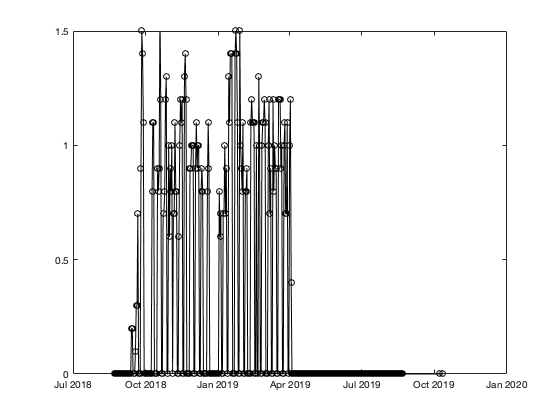

water_date = datetime(water_date);
figure; plot(water_date, earned_water, 'ko-')
ylim([0, 1.5])

Weight as a function of date.

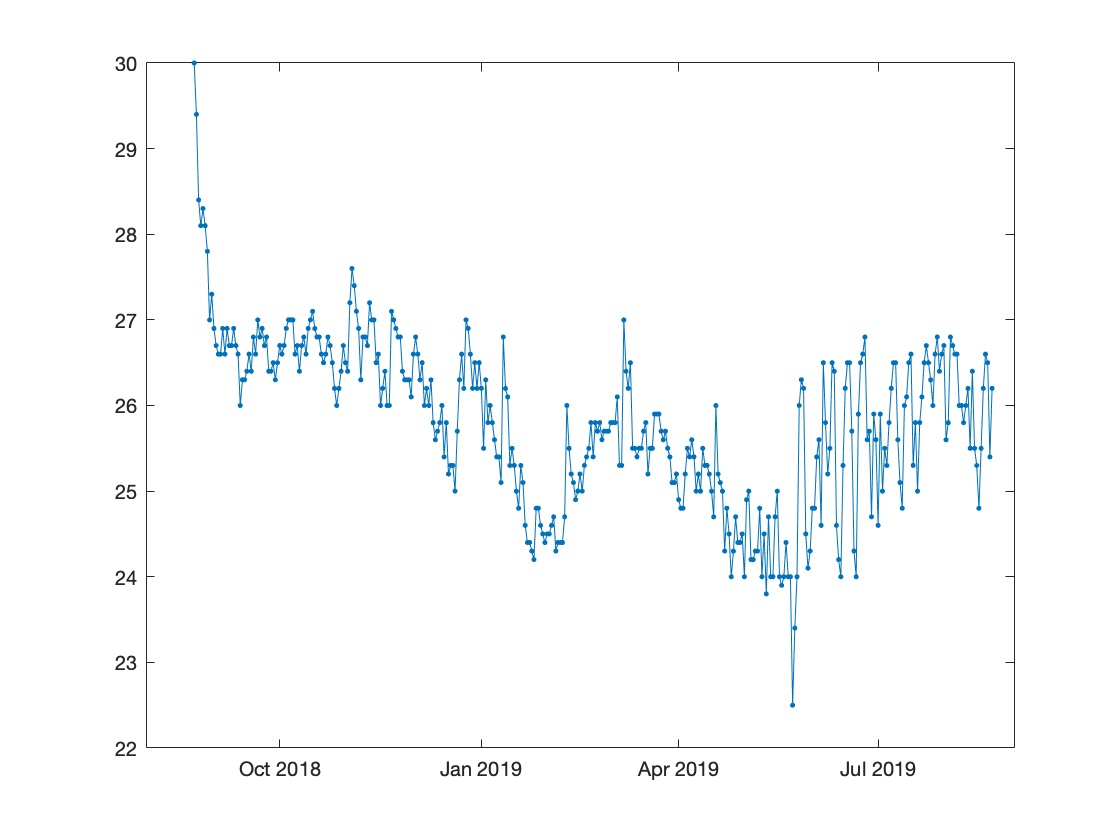

[weighing_date, weight] = fetchn(...
    action.Weighing & subj_key, 'DATE(weighing_time)->weighing_date', 'weight');
weighing_date = datetime(weighing_date);
figure; plot(weighing_date, weight, '.-')

Plot both together:

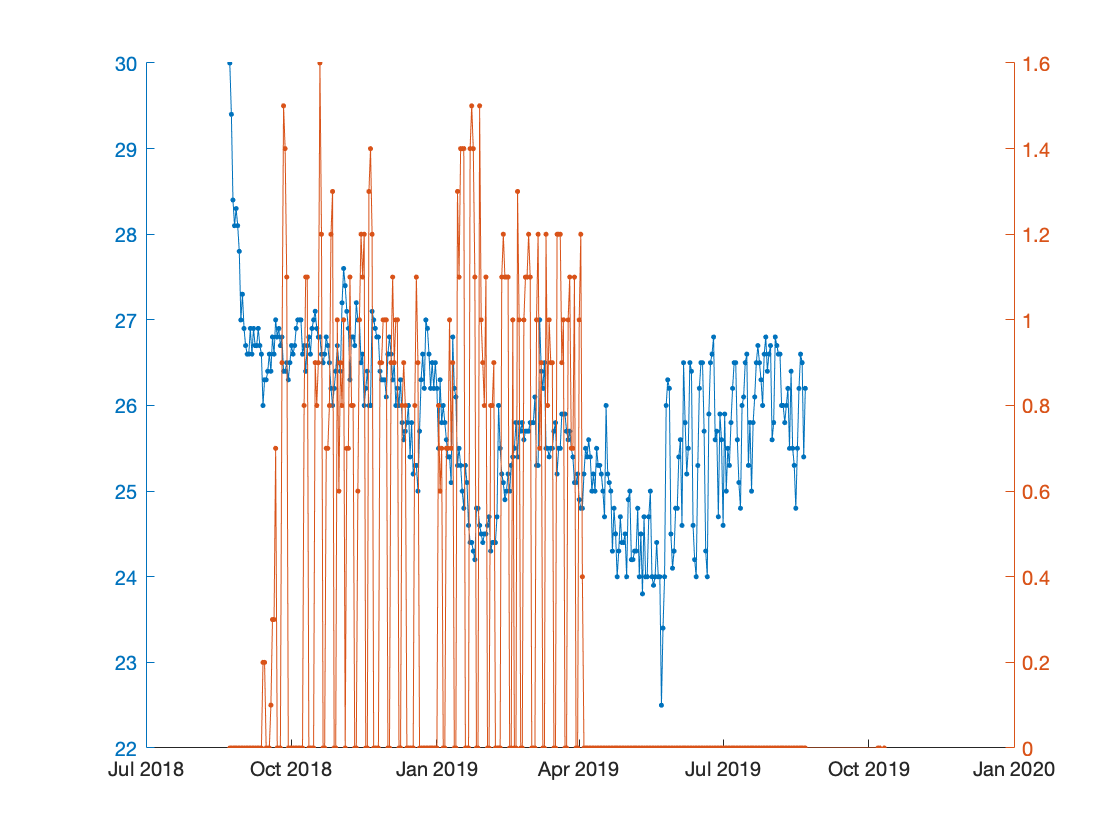

figure; hold on
yyaxis left
plot(weighing_date, weight, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

Performance as a function of date

acquisition.Session

ans = Object acquisition.Session

 ::  ::

    USER_ID    SUBJECT_ID    SESSION_DATE    SESSION_NUMBER     session_start_time        session_end_time        location       task      level    set_id    stimulus_bank    stimulus_commit    stimulus_set    ball_squal    session_performance    session_narrative    protocol    version_info
    _______    __________    ____________    ______________    _____________________    _____________________    __________    ________    _____    ______    _____________

acquisition.Session & subj_key

ans = Object acquisition.Session

 ::  ::

    USER_ID     SUBJECT_ID    SESSION_DATE    SESSION_NUMBER     session_start_time        session_end_time        location       task      level    set_id    stimulus_bank    stimulus_commit    stimulus_set    ball_squal    session_performance    session_narrative    protocol    version_info
    ________    __________    ____________    ______________    _____________________    _____________________    __________    ________    _____    ______    _____________

Plot performance as a function of date.

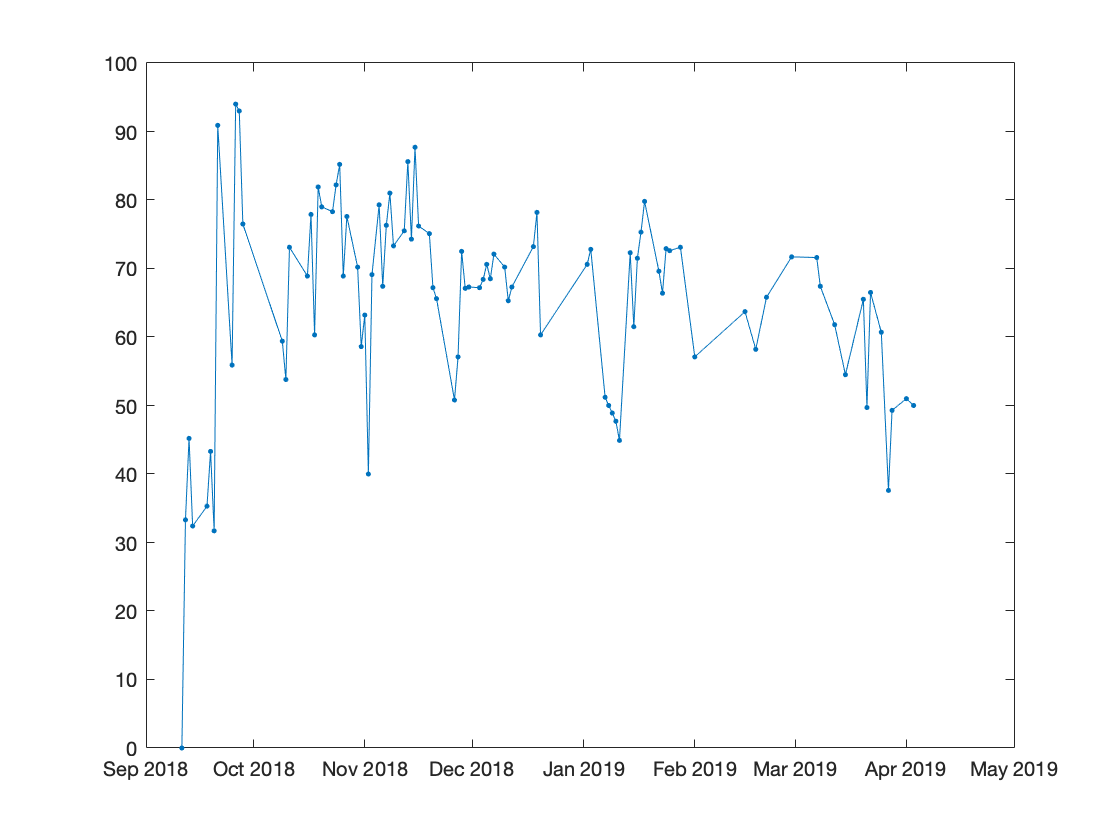

[session_date, performance] = fetchn(acquisition.Session & subj_key, 'session_date', 'session_performance');
session_date = datetime(session_date);
figure; plot(session_date, performance, '.-')

Plot both performance and earned water as a function of date.

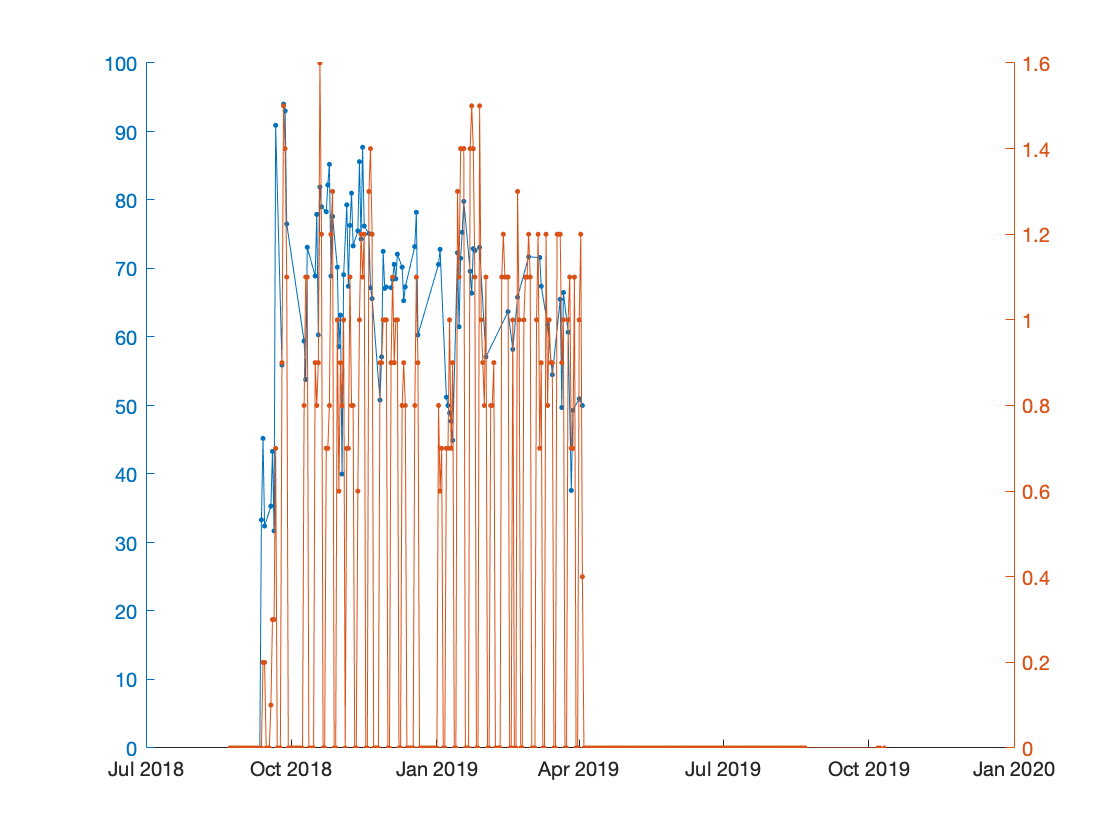

figure; hold on
yyaxis left
plot(session_date, performance, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

Compute trial numbers of a given date.

acquisition.TowersBlockTrial & subj & 'session_date="2018-09-20"'

ans = Object acquisition.TowersBlockTrial

 ::  ::

    USER_ID     SUBJECT_ID    SESSION_DATE    SESSION_NUMBER    BLOCK    TRIAL_IDX    trial_type    choice    trial_abs_start    trial_duration    excess_travel    i_arm_entry    i_blank    i_cue_entry    i_mem_entry    i_turn_entry    iterations    trial_id    trial_prior_p_left    vi_start    trial_time    collision    cue_presence_left    cue_presence_right    cue_onset_left    cue_onset_right    cue_offset_left    cue_offset_right    cue_pos_left 

Compute trial numbers of each date

query = acquisition.Session & subj_key

query = Object acquisition.Session

 ::  ::

    USER_ID     SUBJECT_ID    SESSION_DATE    SESSION_NUMBER     session_start_time        session_end_time        location       task      level    set_id    stimulus_bank    stimulus_commit    stimulus_set    ball_squal    session_performance    session_narrative    protocol    version_info
    ________    __________    ____________    ______________    _____________________    _____________________    __________    ________    _____    ______    _____________

[session_date, n_trials] = fetchn(query.aggr(acquisition.TowersBlockTrial, 'count(*) -> n'), 'session_date', 'n');
session_date = datetime(session_date);

figure; hold on

yyaxis left
plot(session_date, performance, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

## Summary

In session 1, we have covered basic methods to explore, browse and fetch data from the data pipeline. In the next session, we will learn how to generate different kinds of tables, ingest, delete, and compute entries.